# **Ch7 Binary image morphological processing**

## **Strcuture element**


SE2 = strel('square',3)
SE3 = strel('diamond',2)
SE4 = strel('disk',3)
SE5 = strel('sphere',3)
SE6 = strel('line',5,45)

SE=[1,1,1,1;1,1,1,1;1,1,1,1];
% SE1 = strel('rectangle',MN)

## **Erosion operator 1**

im_input = imread('.\Pics\Ch07\wirebond_mask.tif');
figure, imshow(im_input),title('输入图像');

se1 = strel('diamond', 2);
im_output1 = imerode(im_input, se1);

se2 = [0 0 1 0 0; 0 1 1 1 0; 1 1 1 1 1;0 1 1 1 0;0 0 1 0 0];
im_output2 = imerode(im_input, se2);

figure, imshow([im_output1,im_output2]),title('腐蚀结果 ');

imoutput3 = xor(im_output1,im_output2);
figure, imshow(imoutput3),title('腐蚀结果对比 ');

## **Erosion operator 2**

im_input = imread('.\Pics\Ch07\wirebond_mask.tif');
figure, imshow(im_input),title('输入图像');

se1 = strel('square', 11);
im_output1 = imerode(im_input, se1);

se2 = strel('square', 15);
im_output2 = imerode(im_input, se2);

se3 = strel('square', 45);
im_output3 = imerode(im_input, se3);

figure, imshow([im_output1,im_output2 im_output3]),title('腐蚀结果对比 ');

## **Dilation operator 1**

im_input = imread('.\Pics\Ch07\broken_text.tif');
figure, imshow(im_input),title('输入图像');

se1 = strel('disk', 1);
im_output1 = imdilate(im_input, se1);
% im_output1 = imdilate(im_output1, se1);
% im_output1 = imdilate(im_output1, se1);
figure, imshow(im_output1),title('膨胀结果 ');

## **Dilation operator 2**

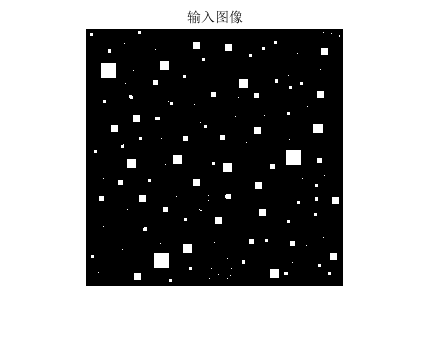

im_input = imread('.\Pics\Ch07\small_squares.tif');
figure, imshow(im_input),title('输入图像');

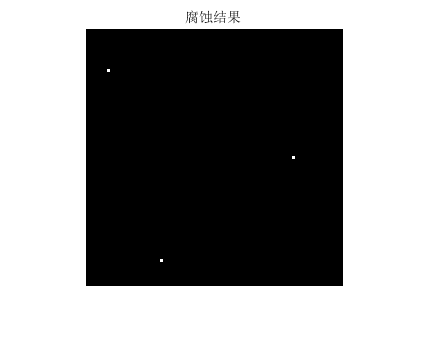


se1 = strel('square', 13);
im_output1 = imerode(im_input, se1);
figure, imshow(im_output1),title('腐蚀结果 ');


im_output2 = imdilateimerode(im_output1, se1);

未定义函数或变量 'imdilateimerode'。

figure, imshow(im_output2),title('膨胀结果 ');

## Open and Close 1

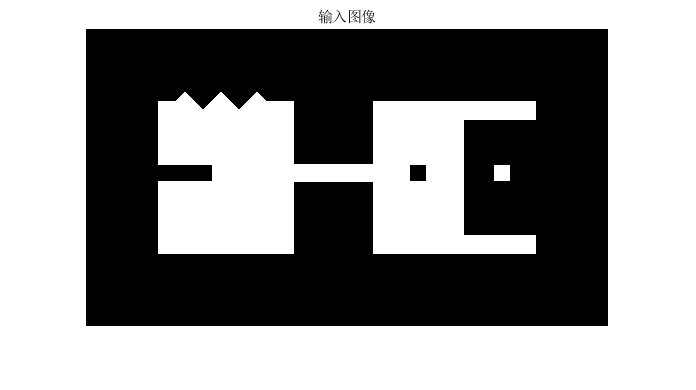

im_input = imread('.\Pics\Ch07\shapes.tif');
figure, imshow(im_input),title('输入图像');

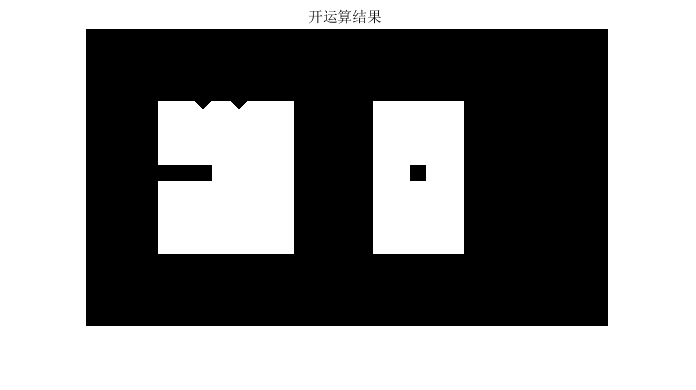


se1 = strel('square', 20);
im_output1 = imopen(im_input, se1);
figure, imshow(im_output1),title('开运算结果 ');

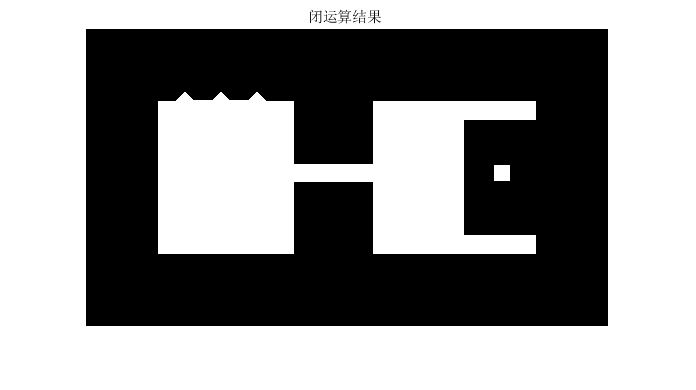


im_output2 = imclose(im_input, se1);
figure, imshow(im_output2),title('闭运算结果 ');

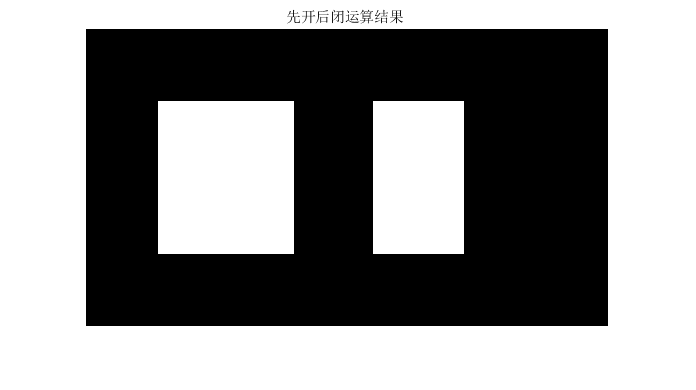


im_output3 = imclose(im_output1, se1);
figure, imshow(im_output3),title('先开后闭运算结果 ');

## Open and Close 2

im_input = imread('.\Pics\Ch07\noisy_fingerprint.tif');
figure, imshow(im_input),title('输入图像');

se1 = strel('square', 3);
im_output1 = imclose(im_input, se1);
figure, imshow(im_output1),title('开运算结果 ');

im_output2 = imopen(im_output1, se1);
figure, imshow(im_output2),title('再进行闭运算结果 ');

## Hit and missing transform

im_input = imread('.\Pics\Ch07\small_squares.tif');
figure, imshow(im_input),title('输入图像');

B1 = strel([0 0 0; 0 1 1; 0 1 0]);
B2 = strel([1 1 1; 1 0 0; 1 0 0]);
im_output = bwhitmiss(im_input, B1, B2);
figure, imshow(im_output), title('HMT result');

## boundary extraction

im_input = imread('.\Pics\Ch07\man.jpg');
im_input = im2bw(im_input,0.5);
figure, imshow(im_input),title('输入图像');

SE1 = strel('disk',3);
SE2 = strel('square',15);

im_output1 = imerode(im_input, SE1);
im_output2 = imerode(im_input, SE2);

im_output1 = im_input-im_output1;
im_output2 = im_input-im_output2;

im_output3 = bwmorph(im_input,'remove');

figure, imshow([im_output1 im_output2 im_output3]), title('boundary extraction result');

## Hole filling

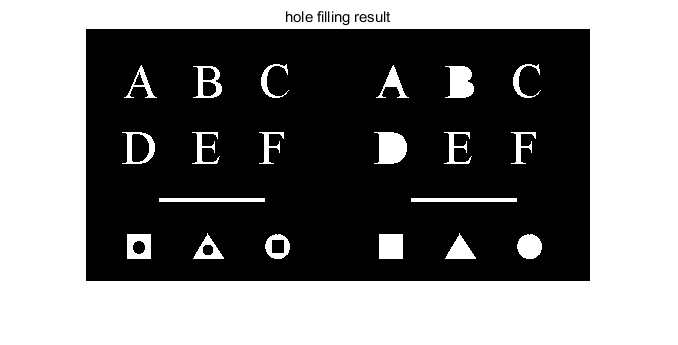

im_input = im2bw(rgb2gray(imread('.\Pics\Ch07\ten_objects2.jpg')),0.5);
%figure, imshow(im_input),title('输入图像');

im_output1 = imfill(im_input, 'holes');

figure, imshow([im_input im_output1]), title('hole filling result');

## Connected component extraction

im_input = imread('.\Pics\Ch07\ten_objects.tif');
figure, imshow(im_input),title('输入图像');

im_output1 = bwlabel(im_input,8);

im_output1 = im2double(im_output1/max(im_output1(:)));
figure, imshow(im_output1), title('Connected component extraction result');

## Thin

im_input = imread('.\Pics\Ch07\bone.tif');
figure, imshow(im_input),title('输入图像');

im_output1 = bwmorph(im_input,'thin',Inf);

figure, imshow(im_output1), title('Connected component extraction result');

## Thicken

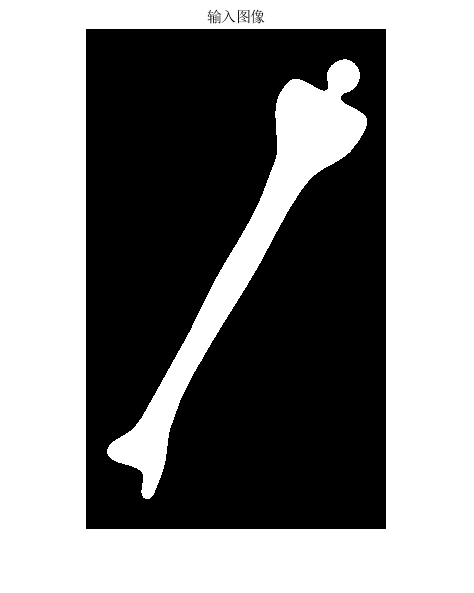

im_input = imread('.\Pics\Ch07\bone.tif');
figure, imshow(im_input),title('输入图像');

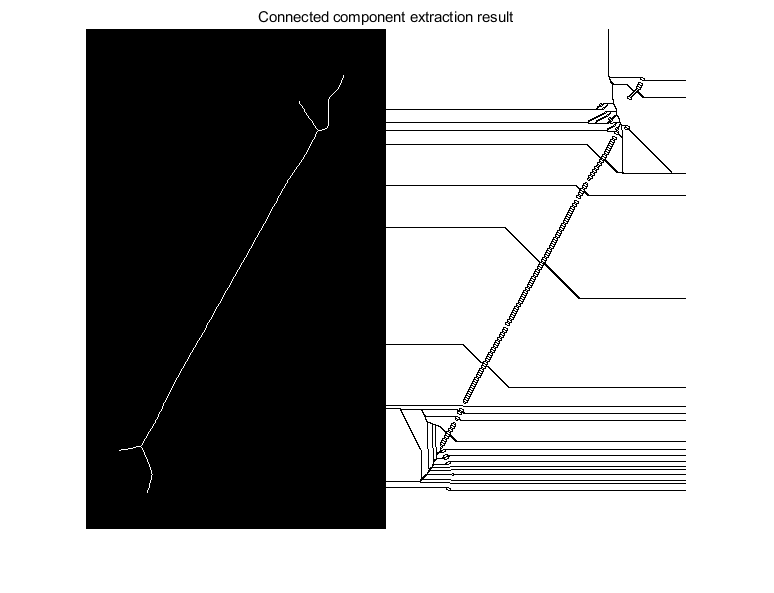


im_output1 = bwmorph(im_input,'thin',Inf);

im_output2 = bwmorph(im_output1,'thicken',Inf);

figure, imshow([im_output1 im_output2]), title('Connected component extraction result');

## Skeleton

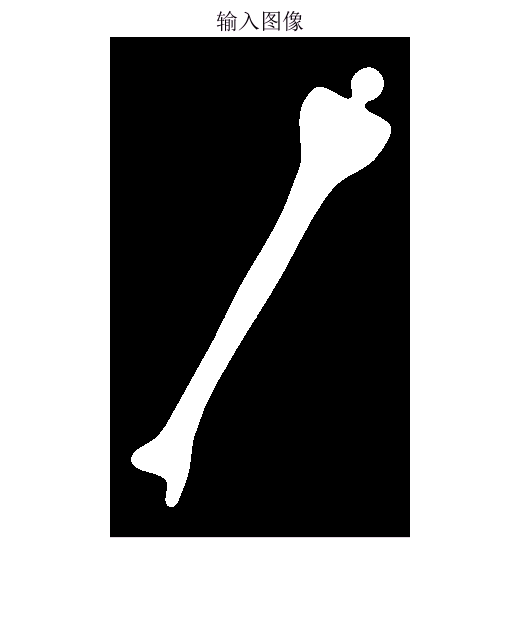

im_input = imread('.\Pics\Ch07\bone.tif');
figure, imshow(im_input),title('输入图像');

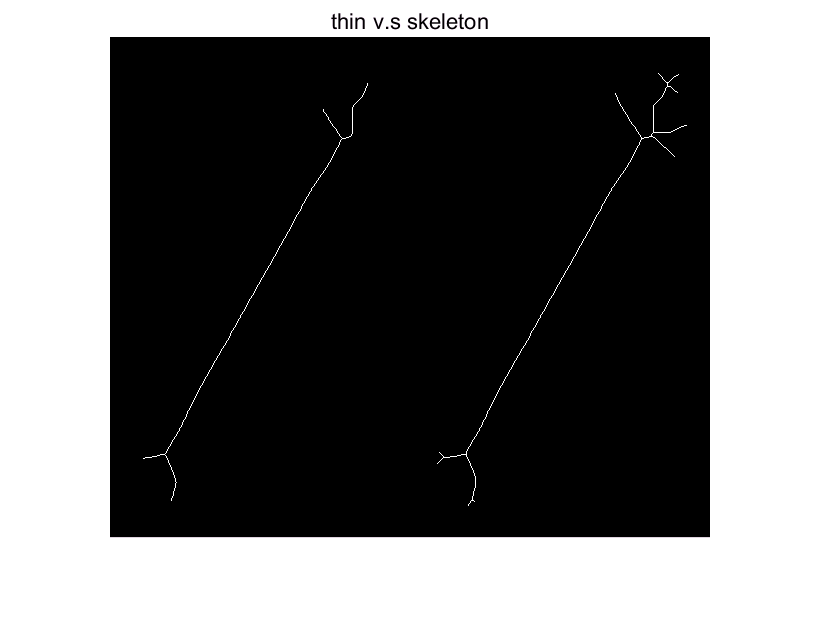


im_output1 = bwmorph(im_input,'thin',Inf);

im_output2 = bwmorph(im_input,'skel',Inf);

figure, imshow([im_output1 im_output2]), title('thin v.s skeleton');

## Pruning

im_input = imread('.\Pics\Ch07\bone.tif');
figure, imshow(im_input),title('输入图像');

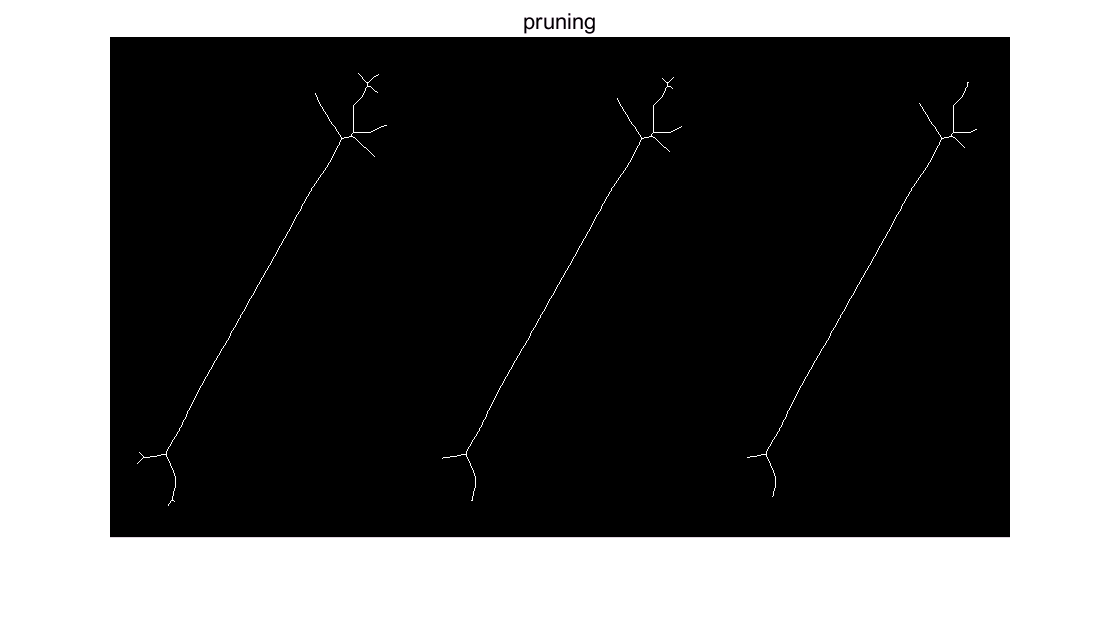


im_output1 = bwmorph(im_input,'skel',Inf);
im_output2 = bwmorph(im_output1,'spur',5);
im_output3 = bwmorph(im_output1,'spur',10);
figure, imshow([im_output1 im_output2 im_output3]), title('pruning');

## Morphological dilation reconstruction

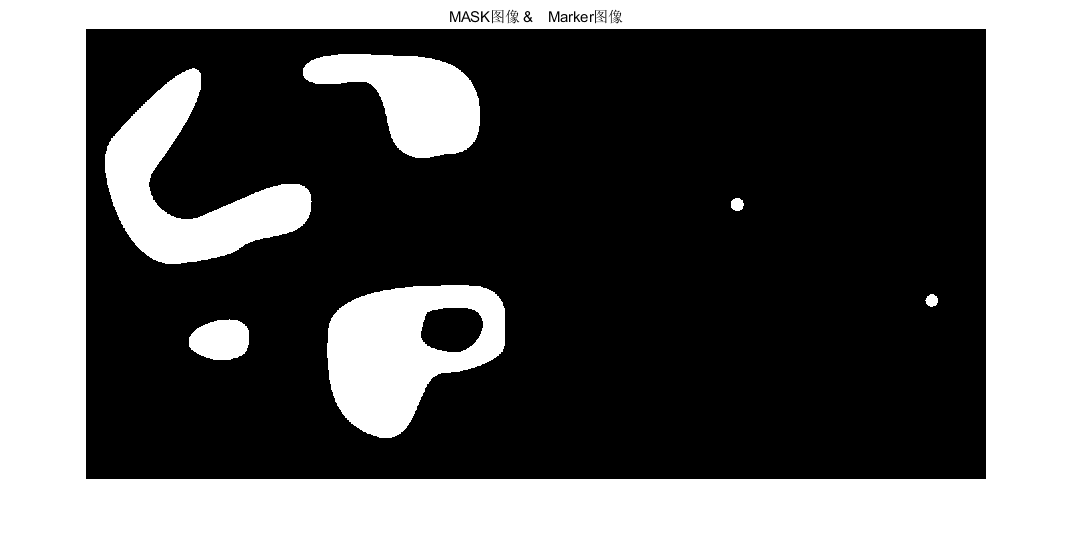

im_mask = im2bw(imread('.\Pics\Ch07\recon_mask.tif'), 0.5);
% figure, imshow(im_mask),title('MASK图像');MASK图像
im_marker = im2bw(imread('.\Pics\Ch07\recon_marker.tif'),0.8);
figure, imshow([im_mask im_marker]),title('MASK图像 &　Marker图像');

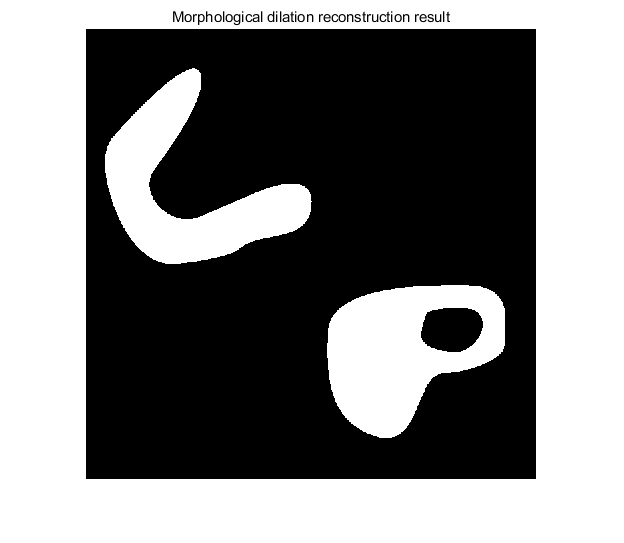


im_output = imreconstruct(im_marker,im_mask);
figure, imshow(im_output), title('Morphological dilation reconstruction result');

## Morphological open reconstruction

im_mask = imread('.\Pics\Ch07\book_text.tif');
im_erode = imerode(im_mask, ones(51,1));

im_open = imopen(im_mask, ones(51,1));
im_output = imreconstruct(im_erode, im_mask);
figure, imshow([im_mask im_erode; im_open im_output]), title('Morphologicalopen reconstruction result');